## Foil Study - Running XFOIL simulations

**Notes:** 

- this script reproduces the foil study and uses XFOIL for MATLAB. Download here: [https://www.mathworks.com/matlabcentral/fileexchange/50070-xfoil-for-matlab](https://www.mathworks.com/matlabcentral/fileexchange/50070-xfoil-for-matlab) and add the installation folder to your MATLAB path before proceeding. 

- Use the `Generating_points.mlx` live script file in MATLAB to generate the parameter lists required to run the studies.

- Use the RMD file `Creating_cambers.RMD` in RStudio ***or*** `Creating_cambers_MATLAB.mlx` in MATLAB before running this MATLAB script. It will produce the necessary camber files used in the analysis.

### Example simulation in XFOIL for MATLAB

This section guides you through running through a single example simulation with the template airfoil (AS6091) used in the studies.  Run this section to complete the simulation. 

Loading 2D template airfoil: 

foil = readtable("../data/airfoils/AS6091.dat");
X = foil{:, 1};
Y = foil{:, 2};

Plot foil:  

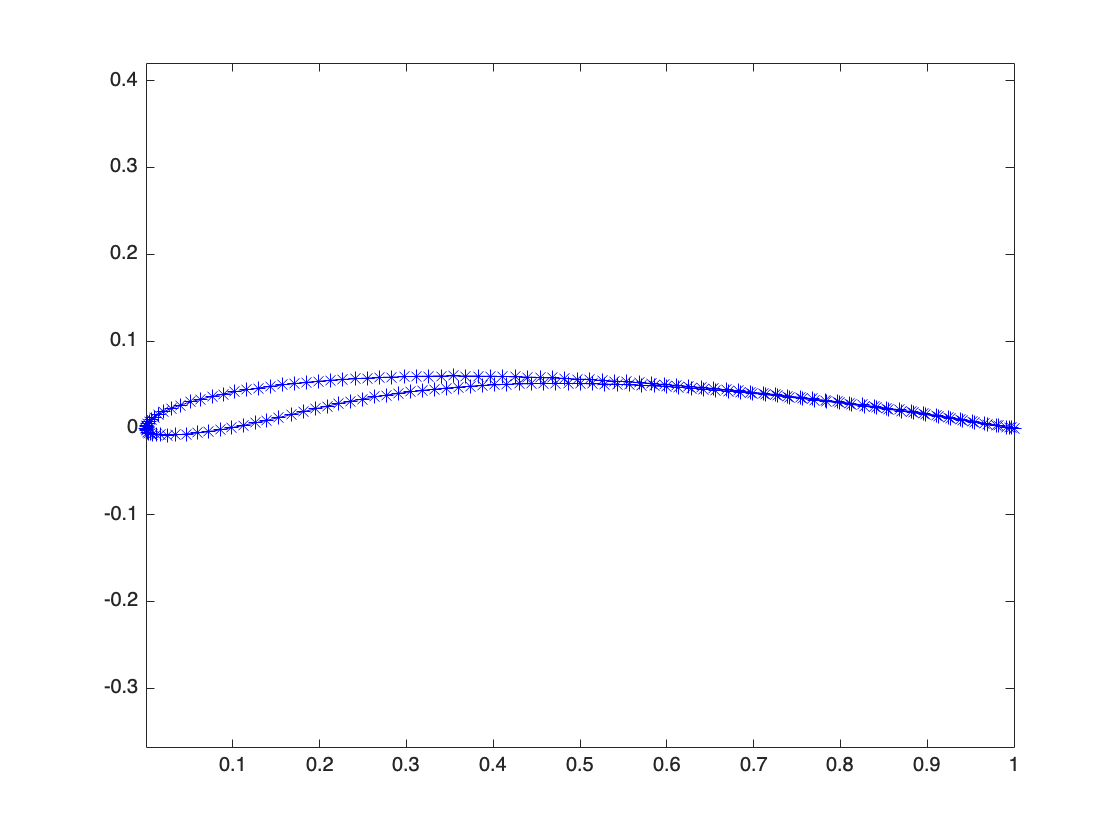

plot(X, Y, 'b*-')
axis equal

Set parameters: 

RE = 1e9;
MACH = 0;
aoa = 0.1;

Run XFOIL: 

tic
[p] = xfoil(X, Y, aoa, RE, MACH);

calculating unit vorticity distributions ...
 Calculating wake trajectory ...\r\p.n
calculating source influence matrix ...
 initializing bl ...
    Side %d ...\r\n
    Side %d ...\r\n
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
----------CONVERGED----------\r\n\r\n


toc

Elapsed time is 7.479546 seconds.


Results: 

coefficient of lift (CL):

p.cl

ans = 0.6010

coefficient of drag (CD):

p.cd

ans = 0.0036

coefficient of pitching moment (CM):

p.cm

ans = -0.1338

Visualize pressure results: 

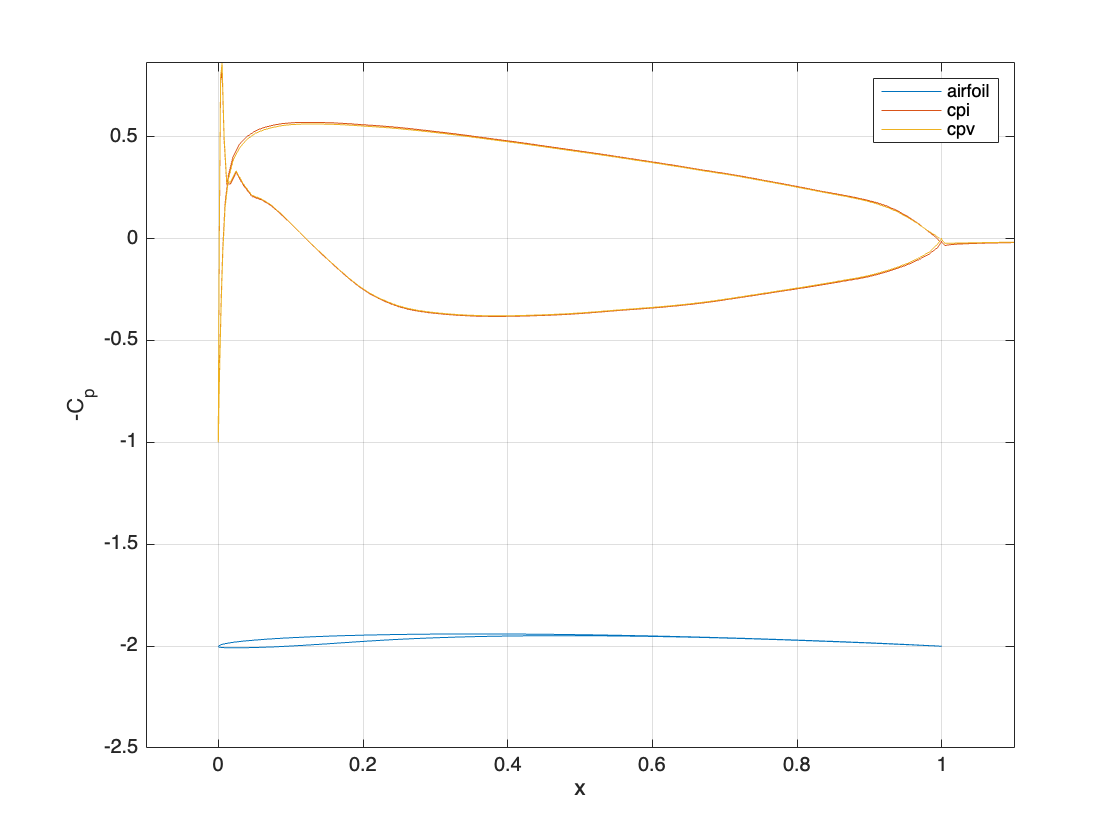

figure(2)
plot(p.xb, p.yb-2, p.x, -p.cpi, p.x, -p.cpv)
    xlabel('x')
    ylabel('-C_p')
    legend('airfoil', 'cpi', 'cpv')
    xlim([-0.1 1.1])
    ylim([-2.5 max([-p.cpi, -p.cpv])])
    grid on

### The Full Studies – grid, gPC, and NN

This section runs the entire parameter study based on which parameter set you choose. This will run in parallel with the parallel processing toolbox. You may change the number of workers in your pool by changing clpool. If you don't wish to run in parallel, delete or suppress the lines of code under "create parallel pool" and replace `parfor` with `for`. 

Define the parameter set to run. Options for method are `grid`, `gPC`, or `NN` and for type are `noLogRe` and `LogRe`. There are five possible studies. If `grid` is selected, then type should be `noLogRe`.

method = "NN";
type = "noLogRe";

Create parallel pool:

clpool = 8;
mycluster = parpool(clpool);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


Load parameter list:

params = readtable(append("../data/parameters/", ...
        method, "_Params_", type, ".csv"));
RE = params{:, 1};
aoa = params{:, 2};
camber = params{:, 3};
MACH = 0;

Establish results file:

colnames = {'sim', 'CL', 'CD', 'CM'};
writecell(colnames, append("../results/", ...
    method, "_", type, "_results.csv"))

Run simulations:

parfor j=1:length(aoa)
    foil = readtable(append("../data/airfoils/", ...
        method, "_camber_files/AS_camber_", ...
        num2str(camber(j)), ".dat"));
    X = foil{:, 1};
    Y = foil{:, 2};
    [p] = xfoil(X, Y, aoa(j), RE(j), MACH);
    if(p.lvconv)
        writematrix([j p.cl p.cd p.cm], ...
            append("../results/", method,"_", type, "_results.csv"), ...
                'WriteMode', 'append')
    else
        writematrix([j NaN NaN NaN], ...
                append("../results/", method, "_", type, "_results.csv"),...
                'WriteMode', 'append')
    end
    s = struct("p", p);
    save(append("../results/", method, "_", type, "_matfiles/p_sim",...
        num2str(j), ".mat"), "-fromstruct", s)
end

calculating unit vorticity distributions ...
calculating unit vorticity distributions ...
calculating unit vorticity distributions ...
calculating unit vorticity distributions ...
calculating unit vorticity distributions ...
calculating unit vorticity distributions ...
calculating unit vorticity distributions ...
calculating unit vorticity distributions ...
 Calculating wake trajectory ...\r\p.n
 Calculating wake trajectory ...\r\p.n
 Calculating wake trajectory ...\r\p.n
 Calculating wake trajectory ...\r\p.n
calculating source influence matrix ...
 Calculating wake trajectory ...\r\p.n
calculating source influence matrix ...
calculating source influence matrix ...
calculating source influence matrix ...
 Calculating wake trajectory ...\r\p.n
 Calculating wake trajectory ...\r\p.n
 Calculating wake trajectory ...\r\p.n
calculating source influence matrix ...
calculating source influence matrix ...
calculating source influence matrix ...
calculating source influence matrix ...
 initial

Results will appear in the `results/` folder. A csv file will contain `CL`, `CD`, and `CM` results along with the simulation number. Please note: since the simulations are run in parallel, they appear out of order in the csv file (i.e., in a different order than the parameter files). Be sure to resort them by `sim` (simulation number) so that they match up with the correct parameter combinations.

The output from each simulation xfoil function is also saved in a results folder ending with `_matfiles`. This is the structure `p` that saves information about the specific simulation. These can be loaded into MATLAB for further analysis.